test = rmoutliers(raw_feats_main,"quartiles")

test = 388×6 table
    mmoll     Age    Heightcm    Weightkg    HeartRatebpm     BMI  
    ______    ___    ________    ________    ____________    ______

    7.9444    20        182        80.6           74         24.333
    6.6111    24        170        88.3           86         30.554
    4.2778    24        172        83.2           66         28.123
    6.3889    21        178        86.3           85         27.238
    6.2778    24      172.5        80.5           57         27.053
    7.1667    24      176.5        95.7           64          30.72
    5.3889    22      173.5        59.2           89         19.666
    6.3889    23        186          82           96         23.702
    4.8333    23        177        45.9           89         14.651
    6.3333    22        170 

input = [raw_feats_main.Age.';raw_feats_main.Heightcm.';raw_feats_main.Weightkg.';raw_feats_main.HeartRatebpm.';raw_feats_main.BMI.']

input =    20.0000   56.0000   24.0000   24.0000   21.0000   24.0000   24.0000   22.0000   23.0000   23.0000   22.0000   22.0000   21.0000   22.0000   25.0000   20.0000   20.0000   22.0000   31.0000   19.0000   22.0000   19.0000   40.0000   21.0000   22.0000   35.0000   21.0000   25.0000   20.0000   23.0000   26.0000   22.0000   21.0000   20.0000   20.0000   19.0000   19.0000   19.0000   52.0000   47.0000   22.0000   22.0000   19.0000   22.0000   27.0000   30.0000   20.0000   25.0000   42.0000   21.0000
  182.0000  156.0000  170.0000  172.0000  178.0000  172.5000  176.5000  173.5000  186.0000  177.0000  170.0000  168.0000  177.0000  176.0000  179.5000  182.0000  191.5000  180.5000  176.5000  187.0000  177.5000  172.0000  183.5000  179.5000  175.0000  171.0000  156.5000  157.0000  172.0000  181.0000  167.5000  180.5000  173.0000  178.0000  179.5000  175.5000  170.5000  188.5000  150.0000  168.0000  178.5000  171.5000  163.0000  159.5000  167.5000  158.5000  160.5000  178.5000  160.0000 

output = [raw_feats_main.mmoll.']

output =     7.9444    8.5000    6.6111    4.2778    6.3889    6.2778    7.1667    5.3889    6.3889    4.8333    6.3333    6.3889    5.5556    7.2778    5.5000    7.0556    6.2778    5.9444    5.6111    7.6111    6.3333    5.2222    7.0556   15.2778    7.1667    7.1111    6.3333    5.2222    5.1111    4.8889    9.1111    6.5556    5.8889    6.5000    5.5000    6.6111    7.0556    4.2222    7.2778    6.6111    5.1111    6.8889    7.4444    6.2778   10.0556   10.1111    9.6667    6.6111    7.3333    7.0000


net = fitnet([10 8])

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 98
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      in

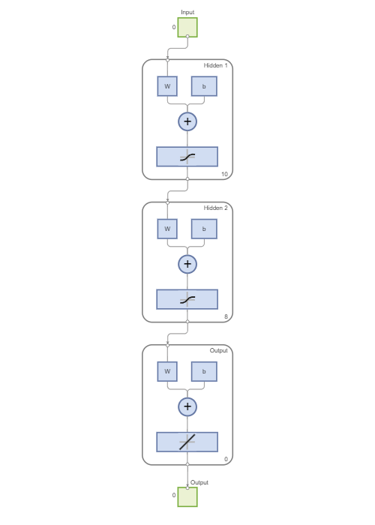

view(net)

net.divideParam.trainRatio = 0.7

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 98
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      in

net.divideParam.valRatio = 0.15

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 98
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      in

net.divideParam.testRatio = 0.15

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 98
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      in

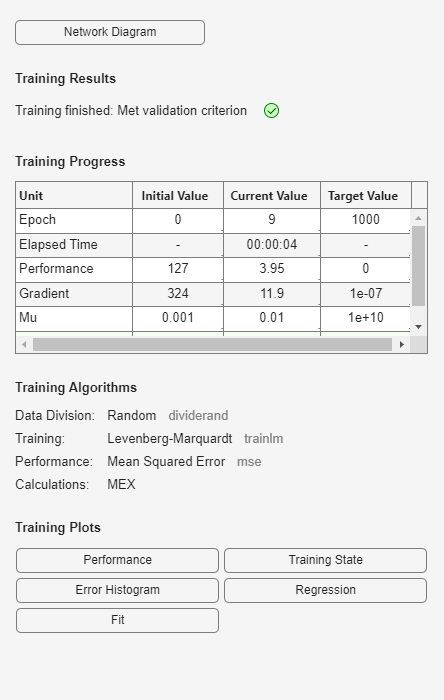

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 157
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      i

tr = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1 2 4 5 6 7 11 12 13 15 17 18 20 21 22 23 26 27 28 29 30 31 32 33 34 36 37 38 39 40 41 44 46 47 48 50 52 54 55 57 58 59 61 62 63 65 66 67 68 70 72 73 74 75 76 77 78 79 80 81 82 83 84 85 89 90 91 95 96 97 98 99 100 … ] (1×323 double)
          valInd: [3 8 9 10 16 19 25 45 53 56 86 88 94 106 107 115 116 122 137 139 140 147 148 157 159 163 169 173 178 183 187 194 215 225 227 232 239 240 247 250 252 254 255 262 266 268 269 272 278 288 290 296 305 307 316 322 329 332 … ] (1×69 double)
         testInd: [14 24 35 42 43 49 51 60 64 69 71 87 92 93 117 131 133 135 145 152 171 185 198 199 204 208 217 228 229 236 264 273 277 280 281 283 289 302 304 308 309 311 313 319 321 330 331 334 338 340 364 365 372 380 384 385 386 3

[net,tr] = train(net,input,output)

predictions = net(input)

predictions =     7.4491    8.0865    7.6194    7.2652    7.5530    7.1122    7.5904    7.3384    7.6866    7.1426    7.2746    7.3508    7.5709    7.5152    7.2375    7.2629    7.7282    7.4411    7.3779    7.8169    7.6748    8.1344    9.3425    7.8400    7.1137    8.4366    7.4839    7.6846    7.9449    6.9940    9.3632    8.0803    7.5341    7.4723    8.1995    7.3386    7.6010    7.5447    7.6811    9.2070    7.3373    7.6391    7.5267    7.5881    7.3597    7.1265   10.0455    7.0955    8.2108    7.5863


errors = gsubtract(output,predictions)

errors =     0.4954    0.4135   -1.0083   -2.9874   -1.1641   -0.8344   -0.4237   -1.9495   -1.2977   -2.3093   -0.9413   -0.9619   -2.0153   -0.2374   -1.7375   -0.2073   -1.4504   -1.4967   -1.7667   -0.2057   -1.3415   -2.9122   -2.2869    7.4378    0.0530   -1.3255   -1.1506   -2.4624   -2.8338   -2.1051   -0.2521   -1.5248   -1.6452   -0.9723   -2.6995   -0.7275   -0.5454   -3.3225   -0.4033   -2.5959   -2.2262   -0.7502   -0.0823   -1.3103    2.6958    2.9846   -0.3788   -0.4844   -0.8775   -0.5863


performance = perform(net,output,predictions)

performance = 6.8794

net.trainFcn = "trainbr"

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 157
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      i

net.trainFcn = "trainscg"

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 157
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      i